% Load the XDF library (Ensure the XDF library is added to your MATLAB path)
addpath('C:\Users\Brandon\Documents\MATLAB\xdf-Matlab-master'); % Replace with the path to the XDF MATLAB library

% Specify the path to your XDF file
xdf_file_path = 'C:\Users\Brandon\Documents\2025 Fall\EEG_Analysis\Peyton_Visual.xdf'; % Replace with your .xdf file's path

% Load the XDF file
disp('Loading XDF file...');

Loading XDF file...


[streams, fileheader] = load_xdf(xdf_file_path);

% Display all streams
disp('Available Streams:');

Available Streams:


for i = 1:length(streams)
    fprintf('Stream #%d\n', i);
    fprintf('  Name: %s\n', streams{i}.info.name);
    fprintf('  Type: %s\n', streams{i}.info.type);
    fprintf('  Channel Count: %s\n', streams{i}.info.channel_count);
    fprintf('  Nominal Sampling Rate: %s\n', streams{i}.info.nominal_srate);
    fprintf('  Time Series Length: %d samples\n', size(streams{i}.time_series, 1));
    fprintf('  Data Type: %s\n', streams{i}.info.type);
    fprintf('  Unique ID: %s\n\n', streams{i}.info.source_id);
end

Stream #1


  Name: MarkerStream


  Type: Markers


  Channel Count: 2


  Nominal Sampling Rate: 0.000000000000000


  Time Series Length: 2 samples


  Data Type: Markers


  Unique ID: marker_stream_id



Stream #2


  Name: eegoSports-000170_markers


  Type: Markers


  Channel Count: 1


  Nominal Sampling Rate: 0.000000000000000


  Time Series Length: 1 samples


  Data Type: Markers


  Unique ID: eegoSports_000170_markers



Stream #3


  Name: eegoSports 000170


  Type: EEG


  Channel Count: 39


  Nominal Sampling Rate: 512.0000000000000


  Time Series Length: 39 samples


  Data Type: EEG


  Unique ID: eegoSports_000170




disp('Stream display complete.');

Stream display complete.



eeg_stream = streams{1,3};
eeg_data = eeg_stream.time_series;
disp(size(eeg_data))

          39     1256179



num_channels = size(eeg_data, 1);
num_samples = size(eeg_data, 2);
channel_labels = cell(1, numel(num_channels));

for s=1:num_channels
    channel_labels{s} = streams{1, 3}.info.desc.channels.channel{1, s}.label
end

channel_labels = 1×1 cell array
    {'FP1'}


channel_labels = 1×2 cell array
    {'FP1'}    {'FPZ'}


channel_labels = 1×3 cell array
    {'FP1'}    {'FPZ'}    {'FP2'}


channel_labels = 1×4 cell array
    {'FP1'}    {'FPZ'}    {'FP2'}    {'F7'}


channel_labels = 1×5 cell array
    {'FP1'}    {'FPZ'}    {'FP2'}    {'F7'}    {'F3'}


channel_labels = 1×6 cell array
    {'FP1'}    {'FPZ'}    {'FP2'}    {'F7'}    {'F3'}    {'FZ'}


channel_labels = 1×7 cell array
    {'FP1'}    {'FPZ'}    {'FP2'}    {'F7'}    {'F3'}    {'FZ'}    {'F4'}


channel_labels = 1×8 cell array
    {'FP1'}    {'FPZ'}    {'FP2'}    {'F7'}    {'F3'}    {'FZ'}    {'F4'}    {'F8'}


channel_labels = 1×9 cell array
    {'FP1'}    {'FPZ'}    {'FP2'}    {'F7'}    {'F3'}    {'FZ'}    {'F4'}    {'F8'}    {'FC5'}


channel_labels = 1×10 cell array
    {'FP1'}    {'FPZ'}    {'FP2'}    {'F7'}    {'F3'}    {'FZ'}    {'F4'}    {'F8'}    {'FC5'}    {'FC1'}


channel_labels = 1×11 cell array
    {'FP1'}    {'FPZ'}    {'FP2'}    {'F7'}    {'F3'}    {'FZ'}    {'F4'}    {'F8'}    {'FC5'}    {'FC1'}    {'FC2'}


channel_labels = 1×12 cell array
    {'FP1'}    {'FPZ'}    {'FP2'}    {'F7'}    {'F3'}    {'FZ'}    {'F4'}    {'F8'}    {'FC5'}    {'FC1'}    {'FC2'}    {'FC6'}


channel_labels = 1×13 cell array
    {'FP1'}    {'FPZ'}    {'FP2'}    {'F7'}    {'F3'}    {'FZ'}    {'F4'}    {'F8'}    {'FC5'}    {'FC1'}    {'FC2'}    {'FC6'}    {'M1'}


channel_labels = 1×14 cell array
    {'FP1'}    {'FPZ'}    {'FP2'}    {'F7'}    {'F3'}    {'FZ'}    {'F4'}    {'F8'}    {'FC5'}    {'FC1'}    {'FC2'}    {'FC6'}    {'M1'}    {'T7'}


channel_labels = 1×15 cell array
    {'FP1'}    {'FPZ'}    {'FP2'}    {'F7'}    {'F3'}    {'FZ'}    {'F4'}    {'F8'}    {'FC5'}    {'FC1'}    {'FC2'}    {'FC6'}    {'M1'}    {'T7'}    {'C3'}


channel_labels = 1×16 cell array
    {'FP1'}    {'FPZ'}    {'FP2'}    {'F7'}    {'F3'}    {'FZ'}    {'F4'}    {'F8'}    {'FC5'}    {'FC1'}    {'FC2'}    {'FC6'}    {'M1'}    {'T7'}    {'C3'}    {'CZ'}


channel_labels = 1×17 cell array
    {'FP1'}    {'FPZ'}    {'FP2'}    {'F7'}    {'F3'}    {'FZ'}    {'F4'}    {'F8'}    {'FC5'}    {'FC1'}    {'FC2'}    {'FC6'}    {'M1'}    {'T7'}    {'C3'}    {'CZ'}    {'C4'}


channel_labels = 1×18 cell array
    {'FP1'}    {'FPZ'}    {'FP2'}    {'F7'}    {'F3'}    {'FZ'}    {'F4'}    {'F8'}    {'FC5'}    {'FC1'}    {'FC2'}    {'FC6'}    {'M1'}    {'T7'}    {'C3'}    {'CZ'}    {'C4'}    {'T8'}


channel_labels = 1×19 cell array
    {'FP1'}    {'FPZ'}    {'FP2'}    {'F7'}    {'F3'}    {'FZ'}    {'F4'}    {'F8'}    {'FC5'}    {'FC1'}    {'FC2'}    {'FC6'}    {'M1'}    {'T7'}    {'C3'}    {'CZ'}    {'C4'}    {'T8'}    {'M2'}


channel_labels = 1×20 cell array
    {'FP1'}    {'FPZ'}    {'FP2'}    {'F7'}    {'F3'}    {'FZ'}    {'F4'}    {'F8'}    {'FC5'}    {'FC1'}    {'FC2'}    {'FC6'}    {'M1'}    {'T7'}    {'C3'}    {'CZ'}    {'C4'}    {'T8'}    {'M2'}    {'CP5'}


channel_labels = 1×21 cell array
    {'FP1'}    {'FPZ'}    {'FP2'}    {'F7'}    {'F3'}    {'FZ'}    {'F4'}    {'F8'}    {'FC5'}    {'FC1'}    {'FC2'}    {'FC6'}    {'M1'}    {'T7'}    {'C3'}    {'CZ'}    {'C4'}    {'T8'}    {'M2'}    {'CP5'}    {'CP1'}


channel_labels = 1×22 cell array
    {'FP1'}    {'FPZ'}    {'FP2'}    {'F7'}    {'F3'}    {'FZ'}    {'F4'}    {'F8'}    {'FC5'}    {'FC1'}    {'FC2'}    {'FC6'}    {'M1'}    {'T7'}    {'C3'}    {'CZ'}    {'C4'}    {'T8'}    {'M2'}    {'CP5'}    {'CP1'}    {'CP2'}


channel_labels = 1×23 cell array
    {'FP1'}    {'FPZ'}    {'FP2'}    {'F7'}    {'F3'}    {'FZ'}    {'F4'}    {'F8'}    {'FC5'}    {'FC1'}    {'FC2'}    {'FC6'}    {'M1'}    {'T7'}    {'C3'}    {'CZ'}    {'C4'}    {'T8'}    {'M2'}    {'CP5'}    {'CP1'}    {'CP2'}    {'CP6'}


channel_labels = 1×24 cell array
    {'FP1'}    {'FPZ'}    {'FP2'}    {'F7'}    {'F3'}    {'FZ'}    {'F4'}    {'F8'}    {'FC5'}    {'FC1'}    {'FC2'}    {'FC6'}    {'M1'}    {'T7'}    {'C3'}    {'CZ'}    {'C4'}    {'T8'}    {'M2'}    {'CP5'}    {'CP1'}    {'CP2'}    {'CP6'}    {'P7'}


channel_labels = 1×25 cell array
    {'FP1'}    {'FPZ'}    {'FP2'}    {'F7'}    {'F3'}    {'FZ'}    {'F4'}    {'F8'}    {'FC5'}    {'FC1'}    {'FC2'}    {'FC6'}    {'M1'}    {'T7'}    {'C3'}    {'CZ'}    {'C4'}    {'T8'}    {'M2'}    {'CP5'}    {'CP1'}    {'CP2'}    {'CP6'}    {'P7'}    {'P3'}


channel_labels = 1×26 cell array
    {'FP1'}    {'FPZ'}    {'FP2'}    {'F7'}    {'F3'}    {'FZ'}    {'F4'}    {'F8'}    {'FC5'}    {'FC1'}    {'FC2'}    {'FC6'}    {'M1'}    {'T7'}    {'C3'}    {'CZ'}    {'C4'}    {'T8'}    {'M2'}    {'CP5'}    {'CP1'}    {'CP2'}    {'CP6'}    {'P7'}    {'P3'}    {'PZ'}


channel_labels = 1×27 cell array
    {'FP1'}    {'FPZ'}    {'FP2'}    {'F7'}    {'F3'}    {'FZ'}    {'F4'}    {'F8'}    {'FC5'}    {'FC1'}    {'FC2'}    {'FC6'}    {'M1'}    {'T7'}    {'C3'}    {'CZ'}    {'C4'}    {'T8'}    {'M2'}    {'CP5'}    {'CP1'}    {'CP2'}    {'CP6'}    {'P7'}    {'P3'}    {'PZ'}    {'P4'}


channel_labels = 1×28 cell array
    {'FP1'}    {'FPZ'}    {'FP2'}    {'F7'}    {'F3'}    {'FZ'}    {'F4'}    {'F8'}    {'FC5'}    {'FC1'}    {'FC2'}    {'FC6'}    {'M1'}    {'T7'}    {'C3'}    {'CZ'}    {'C4'}    {'T8'}    {'M2'}    {'CP5'}    {'CP1'}    {'CP2'}    {'CP6'}    {'P7'}    {'P3'}    {'PZ'}    {'P4'}    {'P8'}


channel_labels = 1×29 cell array
    {'FP1'}    {'FPZ'}    {'FP2'}    {'F7'}    {'F3'}    {'FZ'}    {'F4'}    {'F8'}    {'FC5'}    {'FC1'}    {'FC2'}    {'FC6'}    {'M1'}    {'T7'}    {'C3'}    {'CZ'}    {'C4'}    {'T8'}    {'M2'}    {'CP5'}    {'CP1'}    {'CP2'}    {'CP6'}    {'P7'}    {'P3'}    {'PZ'}    {'P4'}    {'P8'}    {'POZ'}


channel_labels = 1×30 cell array
    {'FP1'}    {'FPZ'}    {'FP2'}    {'F7'}    {'F3'}    {'FZ'}    {'F4'}    {'F8'}    {'FC5'}    {'FC1'}    {'FC2'}    {'FC6'}    {'M1'}    {'T7'}    {'C3'}    {'CZ'}    {'C4'}    {'T8'}    {'M2'}    {'CP5'}    {'CP1'}    {'CP2'}    {'CP6'}    {'P7'}    {'P3'}    {'PZ'}    {'P4'}    {'P8'}    {'POZ'}    {'O1'}


channel_labels = 1×31 cell array
    {'FP1'}    {'FPZ'}    {'FP2'}    {'F7'}    {'F3'}    {'FZ'}    {'F4'}    {'F8'}    {'FC5'}    {'FC1'}    {'FC2'}    {'FC6'}    {'M1'}    {'T7'}    {'C3'}    {'CZ'}    {'C4'}    {'T8'}    {'M2'}    {'CP5'}    {'CP1'}    {'CP2'}    {'CP6'}    {'P7'}    {'P3'}    {'PZ'}    {'P4'}    {'P8'}    {'POZ'}    {'O1'}    {'OZ'}


channel_labels = 1×32 cell array
    {'FP1'}    {'FPZ'}    {'FP2'}    {'F7'}    {'F3'}    {'FZ'}    {'F4'}    {'F8'}    {'FC5'}    {'FC1'}    {'FC2'}    {'FC6'}    {'M1'}    {'T7'}    {'C3'}    {'CZ'}    {'C4'}    {'T8'}    {'M2'}    {'CP5'}    {'CP1'}    {'CP2'}    {'CP6'}    {'P7'}    {'P3'}    {'PZ'}    {'P4'}    {'P8'}    {'POZ'}    {'O1'}    {'OZ'}    {'O2'}


channel_labels = 1×33 cell array
    {'FP1'}    {'FPZ'}    {'FP2'}    {'F7'}    {'F3'}    {'FZ'}    {'F4'}    {'F8'}    {'FC5'}    {'FC1'}    {'FC2'}    {'FC6'}    {'M1'}    {'T7'}    {'C3'}    {'CZ'}    {'C4'}    {'T8'}    {'M2'}    {'CP5'}    {'CP1'}    {'CP2'}    {'CP6'}    {'P7'}    {'P3'}    {'PZ'}    {'P4'}    {'P8'}    {'POZ'}    {'O1'}    {'OZ'}    {'O2'}    {'AUX1'}


channel_labels = 1×34 cell array
    {'FP1'}    {'FPZ'}    {'FP2'}    {'F7'}    {'F3'}    {'FZ'}    {'F4'}    {'F8'}    {'FC5'}    {'FC1'}    {'FC2'}    {'FC6'}    {'M1'}    {'T7'}    {'C3'}    {'CZ'}    {'C4'}    {'T8'}    {'M2'}    {'CP5'}    {'CP1'}    {'CP2'}    {'CP6'}    {'P7'}    {'P3'}    {'PZ'}    {'P4'}    {'P8'}    {'POZ'}    {'O1'}    {'OZ'}    {'O2'}    {'AUX1'}    {'AUX2'}


channel_labels = 1×35 cell array
    {'FP1'}    {'FPZ'}    {'FP2'}    {'F7'}    {'F3'}    {'FZ'}    {'F4'}    {'F8'}    {'FC5'}    {'FC1'}    {'FC2'}    {'FC6'}    {'M1'}    {'T7'}    {'C3'}    {'CZ'}    {'C4'}    {'T8'}    {'M2'}    {'CP5'}    {'CP1'}    {'CP2'}    {'CP6'}    {'P7'}    {'P3'}    {'PZ'}    {'P4'}    {'P8'}    {'POZ'}    {'O1'}    {'OZ'}    {'O2'}    {'AUX1'}    {'AUX2'}    {'AUX3'}


channel_labels = 1×36 cell array
    {'FP1'}    {'FPZ'}    {'FP2'}    {'F7'}    {'F3'}    {'FZ'}    {'F4'}    {'F8'}    {'FC5'}    {'FC1'}    {'FC2'}    {'FC6'}    {'M1'}    {'T7'}    {'C3'}    {'CZ'}    {'C4'}    {'T8'}    {'M2'}    {'CP5'}    {'CP1'}    {'CP2'}    {'CP6'}    {'P7'}    {'P3'}    {'PZ'}    {'P4'}    {'P8'}    {'POZ'}    {'O1'}    {'OZ'}    {'O2'}    {'AUX1'}    {'AUX2'}    {'AUX3'}    {'AUX7'}


channel_labels = 1×37 cell array
    {'FP1'}    {'FPZ'}    {'FP2'}    {'F7'}    {'F3'}    {'FZ'}    {'F4'}    {'F8'}    {'FC5'}    {'FC1'}    {'FC2'}    {'FC6'}    {'M1'}    {'T7'}    {'C3'}    {'CZ'}    {'C4'}    {'T8'}    {'M2'}    {'CP5'}    {'CP1'}    {'CP2'}    {'CP6'}    {'P7'}    {'P3'}    {'PZ'}    {'P4'}    {'P8'}    {'POZ'}    {'O1'}    {'OZ'}    {'O2'}    {'AUX1'}    {'AUX2'}    {'AUX3'}    {'AUX7'}    {'AUX8'}


channel_labels = 1×38 cell array
    {'FP1'}    {'FPZ'}    {'FP2'}    {'F7'}    {'F3'}    {'FZ'}    {'F4'}    {'F8'}    {'FC5'}    {'FC1'}    {'FC2'}    {'FC6'}    {'M1'}    {'T7'}    {'C3'}    {'CZ'}    {'C4'}    {'T8'}    {'M2'}    {'CP5'}    {'CP1'}    {'CP2'}    {'CP6'}    {'P7'}    {'P3'}    {'PZ'}    {'P4'}    {'P8'}    {'POZ'}    {'O1'}    {'OZ'}    {'O2'}    {'AUX1'}    {'AUX2'}    {'AUX3'}    {'AUX7'}    {'AUX8'}    {'AUX9'}


channel_labels = 1×39 cell array
    {'FP1'}    {'FPZ'}    {'FP2'}    {'F7'}    {'F3'}    {'FZ'}    {'F4'}    {'F8'}    {'FC5'}    {'FC1'}    {'FC2'}    {'FC6'}    {'M1'}    {'T7'}    {'C3'}    {'CZ'}    {'C4'}    {'T8'}    {'M2'}    {'CP5'}    {'CP1'}    {'CP2'}    {'CP6'}    {'P7'}    {'P3'}    {'PZ'}    {'P4'}    {'P8'}    {'POZ'}    {'O1'}    {'OZ'}    {'O2'}    {'AUX1'}    {'AUX2'}    {'AUX3'}    {'AUX7'}    {'AUX8'}    {'AUX9'}    {'TRIGGER'}



% Extract time series and timestamps
timestamps = eeg_stream.time_stamps; % Corresponding timestamps
marker_times = streams{1,1}.time_stamps;
% Initialize an index array
n_marks = zeros(1, length(marker_times));  % Preallocate for efficiency

% Find the indices of the closest matching timestamps for each marker time
for i = 1:length(marker_times)
    [~, n_marks(i)] = min(abs(timestamps - marker_times(i)));  % Find the closest index
end
% Display the indices
disp('Indices of samples where markers occurred:');

Indices of samples where markers occurred:


disp(n_marks);

  Columns 1 through 13

      553733      570674      570690      571100      572213      572230      572672      573754      573770      575294      575310      576834      576851

  Columns 14 through 26

      577276      578357      578374      579898      579914      581438      581454      582978      582994      583387      584518      584534      584960

  Columns 27 through 39

      586041      586058      586516      587581      587598      588007      589121      589138      589547      590662      590678      591153      592185

  Columns 40 through 52

      592202      592660      593725      593742      594119      595265      595282      596806      596822      597215      598346      598362      598821

  Columns 53 through 65

      599869      599885      600328      601410      601426      601918      602949      602966      604489      604505      604981      606029      606046

  Columns 66 through 78

      606440      607553      607570      607979      609093 

%{
% Plot time series for each EEG channel
n = 1:num_samples;
figure;
hold on;  % Allow multiple lines to be plotted on the same figure
for channel = 1:num_channels
    plot(n, eeg_data(channel, :), 'DisplayName', channel_labels{channel});
end

% Add vertical red lines for each marker index
for i = 1:length(marker_times)
    xline(n(i), 'r', 'LineWidth', 1.5);
end

% Add labels, title, and legend
xlabel('Sample Number (n)');
ylabel('Amplitude');
title('EEG Time Series Data for All Channels (X-Axis: Sample Number)');
legend('Location', 'eastoutside');  % Move the legend outside the plot
grid on;
hold off;  % Release the hold on the plo
% 
%}

## DO NOT ANALYZE 5000 MARKERS

## plot cz and fz

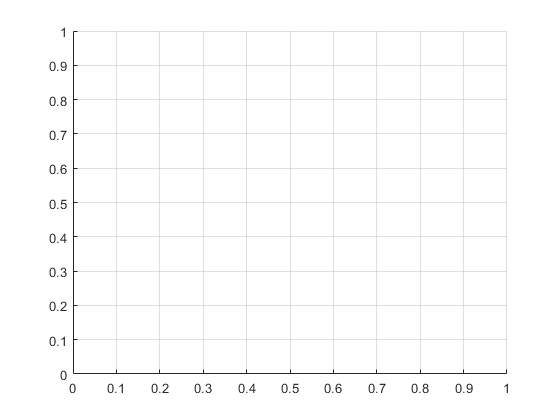


% Filter data (band-pass filtering)
 % Sampling rate (example: 1000 Hz)
 low_cutoff = 1;
 high_cutoff = 15;
 fs = 512;
 [b,a] = butter(2, [low_cutoff, high_cutoff] / (fs / 2));  % 2nd-order Butterworth filter
 filtered_data = filtfilt(b, a, eeg_data);

% % Epoching (extract -200 ms to +800 ms windows)
% epoch_start = -200; % in ms
% epoch_end = 800; % in ms
% baseline_start = -200; % in ms
% baseline_end = 0; % in ms
%
% % (Assume trigger_times contains stimulus onset times in samples)
% epochs = [];
% for i = 1:length(trigger_times)
%     epoch = eeg_data(:, trigger_times(i) + epoch_start:trigger_times(i) + epoch_end);
%     baseline = mean(epoch(:, baseline_start:baseline_end), 2); % Baseline correction
%     epochs = cat(3, epochs, epoch - baseline); % Collect all epochs
% end
%
% % Average ERP for each channel
% erp = mean(epochs, 3);
%
% % Plot ERP for a single channel
% figure;
% plot(epoch_start:epoch_end, erp(1, :)); % Example: Plot ERP for channel 1
% xlabel('Time (ms)');
% ylabel('Amplitude (\muV)');
% title('ERP for Channel 1');
% grid on;
combined_export.filtered_data = filtered_data';
combined_export.triggers = streams{1,1}.time_series;
combined_export.trigger_index = n_marks;

save('preprocessed.mat', 'combined_export');

%figure;
%plot(streams{1,1}.time_series(2,:), streams{1,1}.time_series(1,:));

grid on;